# Parse .hmod Files

Suppose you have KS_JEDC10.hmod in the working directory. Call

clear_hans
hans KS_JEDC10

Parsing...ok!
Compiling dpopt_vfi
Building with 'MinGW64 Compiler (C++)'.
MEX completed successfully.


ans = struct with fields:
               parameters: {'beta'  'sigma'  'r'  'w'}
                var_shock: 'e'
                var_state: 'a'
              var_pre_vfi: 'coh'
               var_policy: 'ap'
                  var_aux: 'c'
                  var_agg: 'K'
            var_agg_shock: 'Z'
           var_agg_params: {'alpha'  'delta'  'L'}
           var_agg_assign: {'r'  'w'}
    var_agg_in_ind_params: {'r'  'w'}
            var_ind_in_eq: 'ap'

As shown, HANS parases the hmod file, compiles the mex files, and returns a structure that describes the model.

clear_hans in the first line clears any caches generated before.

# Solve the Stationary Equilibrium

Call the generated code solve_ss to solve the stationary equilibrium

ss_rslt = solve_ss

Evaluating at var_agg: 43, 
VFI converged (metric_v) 0.00624615, (metric_pol) 0 in 495 iterations
Range of a: 0, 18.9484
Equilbirium residual: 32.0071, 
Evaluating at var_agg: 43.0043, 
VFI converged (metric_v) 0.000289576, (metric_pol) 0 in 307 iterations
Range of a: 0, 18.9484
Equilbirium residual: 32.015, 

     Iteration    Line Search     Func-count      fnorm2^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              2   1.024452e+03   3.200706e+01
Evaluating at var_agg: 38, 
VFI converged (metric_v) 1.19537e-07, (metric_pol) 0 in 1291 iterations
Range of a: 0, 200
Equilbirium residual: -78.1548, 

             1              1              3   6.108174e+03   7.815481e+01   5.000000e+00   1.000000e+00         Newton
Evaluating at var_agg: 38, 
VFI result reused
Range of a: 0, 200
Equilbirium residual: -78.1548, 

             1              2              4   6.108174e+03   7.815481e+01   5.000000e+00   5.000000e-01         Newton


ss_rslt = struct with fields:
                vfi_rslt: [1×1 struct]
                   stats: [1×1 struct]
                 var_agg: [1×1 struct]
                    dist: [2×500 double]
              parameters: [1×1 struct]
          var_agg_params: [1×1 struct]
             shock_trans: [2×2 double]
    shock_invariant_dist: [2×1 double]
                   resid: -7.6537e-07
               exit_flag: 1
               rslt_type: 'ss'
           solver_output: [1×1 struct]
           ind_rslt_dict: [1×1 ArrayKeyMap]

As shown, the function returns a structure that described the solved stationary equilibrium.

We can inspect the values of equilibrium variables:

ss_rslt.var_agg

ans = struct with fields:
    K: 38.2691
    Z: 1
    r: 0.0099
    w: 2.3769
    Y: 3.7139
    I: 0.9567
    C: 2.7571

We can insepct the stationary distribution:

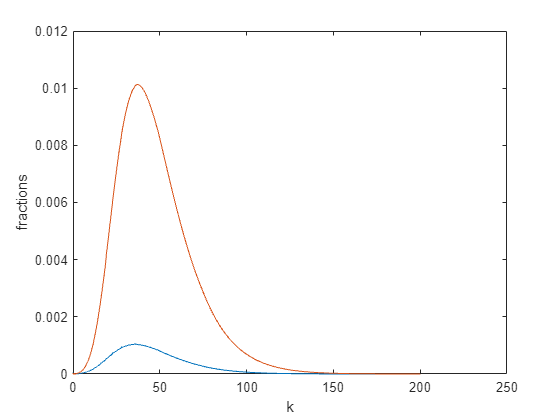

plot(ss_rslt.vfi_rslt.var_state.a, ss_rslt.dist);
xlabel('k');
ylabel('fractions');

And inspect the policy functions

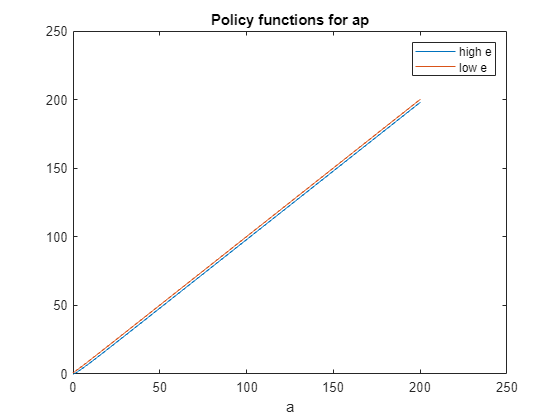

plot(ss_rslt.vfi_rslt.var_state.a, ss_rslt.vfi_rslt.var_policy.ap);
xlabel('a');
title('Policy functions for ap');
legend({'high e','low e'})

# Solve the Transition Path After A Temporay Shock

## Solve the linearized transition path

We first construct the sequence of productivity shock.

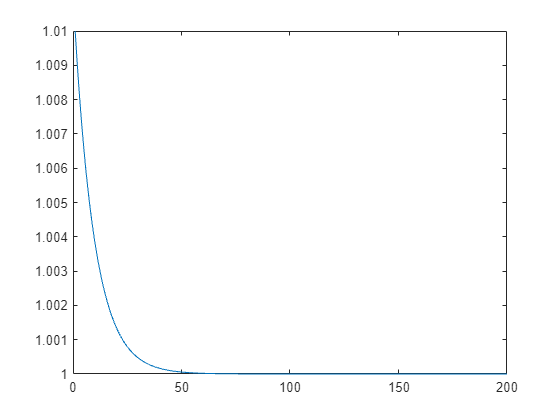

T = 200;
shock_Z = 0.01; rho_Z = 0.9;
Z_t = 1 + shock_Z *rho_Z.^(0:(T-1));
figure;
plot(Z_t)

We then pass the productivity shock and the solved ss_rslt into solve_trans_linear to solve the linearized transition path.

options = struct;
options.T = T;
options.Z_t = Z_t;
trans_linear_rslt = solve_trans_linear(ss_rslt, options)

trans_linear_rslt = struct with fields:
             var_agg_t: [1×1 struct]
       var_agg_shock_t: [1×1 struct]
      jacs_ind_wrt_agg: {[200×200 double]  [200×200 double]}
    jac_eqs_of_var_agg: [200×200 double]
               irf_ssj: [200×200 double]

We can plot the transition path (note that K is the next period capital)

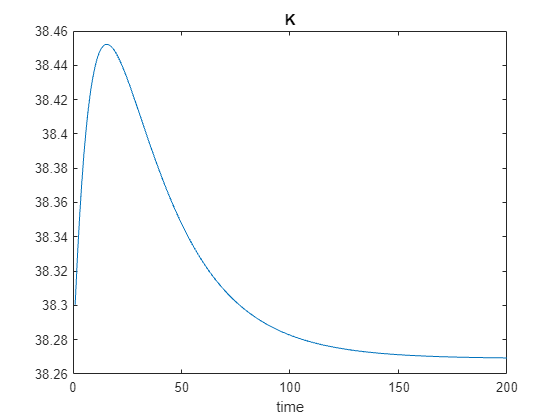

figure;
plot(trans_linear_rslt.var_agg_t.K)
title('K');
xlabel('time');

## Solve the nonlinear transition path

Now we pass the solved ss_rslt to solve_nonlinear_trans(init_ss, final_ss, options) to solve the nonlinear transition path.

Note that we pass ss_rslt as both init_ss and final_ss

trans_nonlinear_rslt = solve_trans_nonlinear(ss_rslt, ss_rslt, options)

     Iteration    Line Search     Func-count      fnorm2^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   3.878220e-04   1.969320e-02

             1              1              2   1.679638e-10   1.296008e-05   2.351472e-03   1.000000e+00        Broyden


trans_nonlinear_rslt = struct with fields:
          var_agg_t: [1×1 struct]
    var_agg_shock_t: [1×1 struct]
           exitflag: 1
             HANS_x: [200×1 double]
          eqs_resid: [200×1 double]
          rslt_type: 'nonlinear_trans'
      solver_output: [1×1 struct]

We compare the solution of the nonlinear transition path and the linear transition path

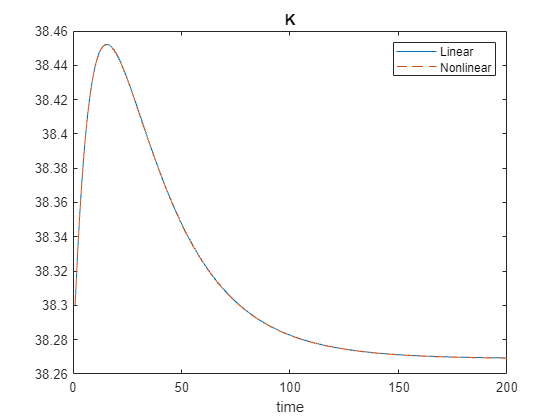

figure;
plot(trans_linear_rslt.var_agg_t.K);
hold on;
plot(trans_nonlinear_rslt.var_agg_t.K, '--');
xlabel('time');
title('K');
legend({'Linear','Nonlinear'});

We can also inspect other defined equilibrium varialbes along the transition path.

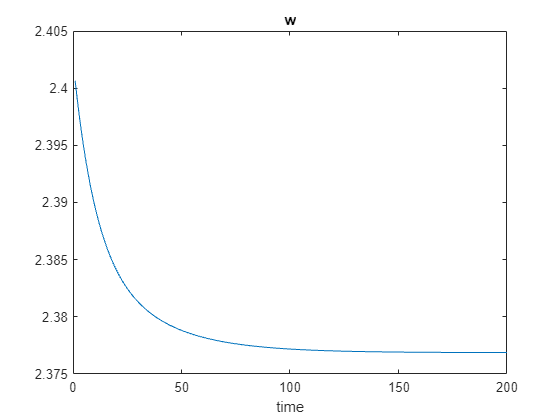

figure;
plot(trans_nonlinear_rslt.var_agg_t.w);
title('w');
xlabel('time');

# Solve the Transition Path After A Permanent Shock

We now consider an unexpected shock that raises Z permanently by 100%.

We first sovle the new stationary equilibrium.

options = struct;
options.Z = 2.0;
ss_rslt_new = solve_ss(options)

Evaluating at var_agg: 43, 
VFI converged (metric_v) 0.0391439, (metric_pol) 0 in 416 iterations
Range of a: 0, 200
Equilbirium residual: -160.841, 
Evaluating at var_agg: 43.0043, 
VFI converged (metric_v) 0.00545253, (metric_pol) 0 in 197 iterations
Range of a: 0, 200
Equilbirium residual: -160.836, 

     Iteration    Line Search     Func-count      fnorm2^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              2   2.586975e+04   1.608408e+02
Evaluating at var_agg: 195.486, 
VFI converged (metric_v) 0.0155154, (metric_pol) 0 in 262 iterations
Range of a: 0, 25.1867
Equilbirium residual: 177.346, 

             1              1              3   3.145175e+04   1.773464e+02   1.524859e+02   1.000000e+00         Newton
Evaluating at var_agg: 119.243, 
VFI converged (metric_v) 0.000426132, (metric_pol) 0 in 590 iterations
Range of a: 0, 95.5869
Equilbirium residual: 75.8402, 

             1              2              4   5.751737e+03  

ss_rslt_new = struct with fields:
                vfi_rslt: [1×1 struct]
                   stats: [1×1 struct]
                 var_agg: [1×1 struct]
                    dist: [2×500 double]
              parameters: [1×1 struct]
          var_agg_params: [1×1 struct]
             shock_trans: [2×2 double]
    shock_invariant_dist: [2×1 double]
                   resid: -7.7448e-05
               exit_flag: 1
               rslt_type: 'ss'
           solver_output: [1×1 struct]
           ind_rslt_dict: [1×1 ArrayKeyMap]

We then solve the transition path from the initial stationary equilibrium to the new stationary equilibrium.

options = struct;
T = 200;
options.Z_t = 2.0*ones(1,T);  % shock hits at period 1
options.T = T;
trans_to_new_ss_rslt = solve_trans_nonlinear(ss_rslt, ss_rslt_new, options)

     Iteration    Line Search     Func-count      fnorm2^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   5.361274e+05   7.322072e+02

             1              1              2   2.784354e+04   1.668638e+02   2.708222e+02   1.000000e+00        Broyden

             2              1              3   2.481739e+03   4.981705e+01   2.913171e+01   1.000000e+00        Broyden

             3              1              4   1.546506e+00   1.243586e+00   5.505432e+00   1.000000e+00        Broyden

             4              1              5   2.603232e-01   5.102187e-01   6.218954e-01   1.000000e+00        Broyden

             5              1              6   2.473192e-04   1.572638e-02   1.128835e-01   1.000000e+00        Broyden

             6              1              7   8.847338e-09   9.406029e-05   2.907495e-03   1.000000e+00        Broyden


trans_to_new_ss_rslt = struct with fields:
          var_agg_t: [1×1 struct]
    var_agg_shock_t: [1×1 struct]
           exitflag: 1
             HANS_x: [200×1 double]
          eqs_resid: [200×1 double]
          rslt_type: 'nonlinear_trans'
      solver_output: [1×1 struct]

We inspect the nonlinear transition path

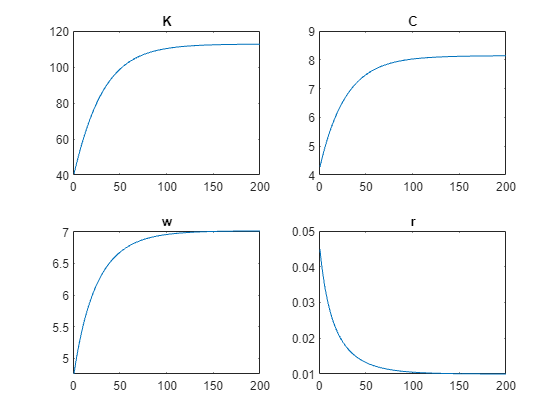

figure;
subplot(2,2,1);
plot(trans_to_new_ss_rslt.var_agg_t.K); title('K');
subplot(2,2,2);
plot(trans_to_new_ss_rslt.var_agg_t.C); title('C');
subplot(2,2,3);
plot(trans_to_new_ss_rslt.var_agg_t.w); title('w');
subplot(2,2,4);
plot(trans_to_new_ss_rslt.var_agg_t.r); title('r');